Initialize:

close all
clear 

V and wavelength for given frequency (single):

T = 22.5; %[C]
freq = 345; %[Hz]
v = vsound_in_air(T);
lam =  lambda_sound_in_air (freq, T);
outstr = sprintf('v = %5.2f[m/s], lam = %5.2f[cm]', v, lam*100);
disp(outstr)

Wavelength for given temp. varying frequency (graph):

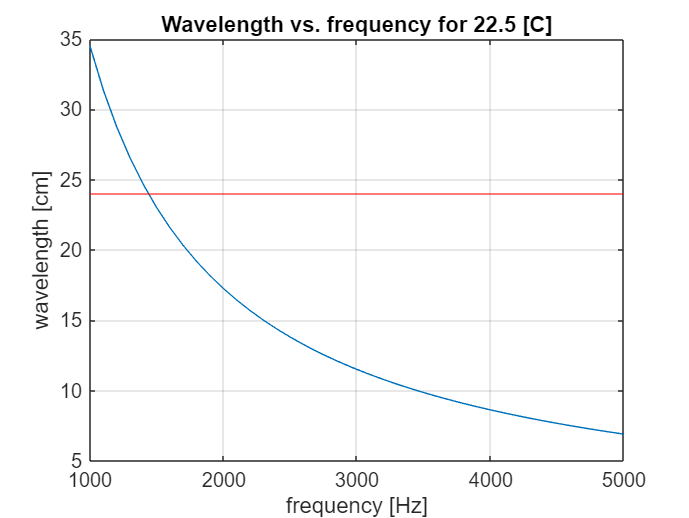

Len_short = 24.; %[cm] approx length of tube for standing wave experiment

T = 22.5; %[C]
freq = 1000:100:5000; %[Hz]
for indf = 1: length(freq)
lamda(indf) = lambda_sound_in_air (freq(indf), T) * 100 ; % wavelength in air [cm]
end

strtitle = sprintf('Wavelength vs. frequency for %3.1f [C]', T);
figure
plot(freq,lamda)
hold on
yline(Len_short, 'r')
title(strtitle)
xlabel('frequency [Hz]')
ylabel('wavelength [cm]')
grid on

Calculating the frequencies for given length:

T = 22.5; %[C]
vsound = vsound_in_air(T);
% n = 1:10;
L = 0.25; %[m]
freq_low = 1000; %lowest frequency 
freq_high = 5500; %highest frequency
n_lowf = floor(2*L/(vsound/freq_low))

n_lowf = 1

n_highf = ceil(2*L/(vsound/freq_high))

n_highf = 8

% lam_nat = 2*L./n;
lam_nat = 2*L./[n_lowf:n_highf];
freq_nat = vsound ./ lam_nat;
freq_nat_in_range = freq_nat((freq_nat > freq_low) & (freq_nat < freq_high));
str_freq = "calc. natural freq in range [Hz]: ";
for indf = 1:length(freq_nat_in_range)
    str_freq = strcat(str_freq, num2str(freq_nat_in_range(indf),'%4.0f'), " ");
end
disp(str_freq)

calc. natural freq in range [Hz]: 1380 2071 2761 3451 4141 4831 


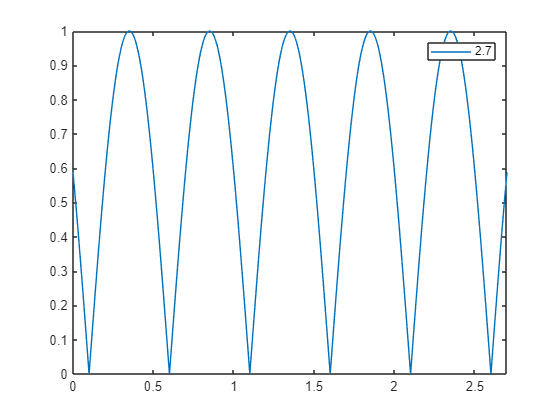


% dphi = pi/2;
% dphi = pi;
dphi = 0;
a = 0.5;

figure
lamda = 1;

% for factor = 2.2:0.2:3
factor = 2.7;
% Len = lamda * 3;
Len = lamda * factor;
% Len = lamda *2.6;
% Len = lamda * factor;
% lamda = Len/factor;

x = 0:0.0001:Len;
tmp = 2*x - Len;

y = abs(2*a*cos(pi/lamda*(2*x - Len)+dphi/2));

plot(x,y,DisplayName= num2str(factor))
% plot(x,y)
hold on
% end

xlim([0 Len])
legend show

Standing waves with coherent sourses, s1 and s2, same amplitude a. Measuring at point x

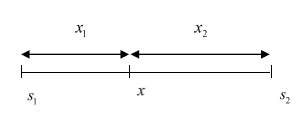

$\phi_0$ is the phase difference between the sources.

Now let's assume the pahse difference is 0 but the amplitude of the sourses is different - a1 and a2


$$\Delta P(x,t) \propto a_1 \cdot cos[2\pi (\frac{x_1}{\lambda}-ft)]+ a_2 \cdot cos[2\pi (\frac{x_2}{\lambda}-ft)]$$


y1 = 2*a*cos(pi/lamda*(2*x - Len));
y2 = 2*a*cos(pi/lamda*(2*x - Len)+pi);
figure
plot(x,y1,x,y2)
